% 観測時間ごとにパラメータ推定
x = importdata("dataset/jumpsizedata.txt")

x =     0.4700    0.7100    0.7100    0.3600    0.2700    0.3600    0.3600    0.4600    0.5100    0.4100    0.4400    0.3900    0.3000    0.4400    0.5100
    0.4600    0.5100    0.4600    0.2600    0.3400    1.0300    0.5600    0.6100    0.4200    1.0800    0.5600    0.4100    0.4400    0.2600    0.3200
    1.1800    0.6800    0.5600    0.7400    0.5000    0.5600    0.2900    0.3500    0.6400    0.8900    0.5700    0.5500    0.7800    0.3500    0.4600
    0.6100    0.4000    0.2600    0.5900    0.6600    0.9100    0.2500    0.3500    0.3900    0.6200    0.3900    0.3900    0.3300    0.3000    0.2300
    0.7900    0.5700    0.5400    0.3500    0.2900    0.6000    0.4700    0.3400    0.6300    0.8400    0.5500    1.2400    0.5400    0.4500    0.3900
    0.8300    0.8800    0.4400    0.6500    0.5200    0.3500    0.4600    0.2900    0.7000    0.6600    0.3300    0.6100    0.5600    0.7500    0.3600
    0.5700    0.6700    0.3300    0.4400    0.4100    0.7200    0.2900    0.3800    0.3200

mulist = zeros (1, length (x))

mulist =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


lambdalist = zeros (1, length (x));
for i=1: length (x)
mlelist = mle(x(i ,:) ,'distribution','InverseGaussian');
mulist (i) = mlelist (1);
lambdalist (i) = mlelist (2) ;
end
% 補間多項式を作成
order = 3;
tdata = 250:250:4000;%時間
intervaldata = 1:1:16; %区間
s1 = csaps (intervaldata, mulist );
sn1 = fnxtr (s1 , order );
s2 = csaps (intervaldata, lambdalist );
sn2 = fnxtr (s2 , order );
mlambdafunc = zeros (1, length (x)+1);
llambdafunc = zeros (1, length (x)+1);
for i=1: length (x)+1
mlambdafunc (i) = polyval (sn1.coefs (i ,:) ,sn1.breaks (i+1) - sn1.breaks (i));
llambdafunc (i) = polyval (sn2.coefs (i ,:) ,sn2.breaks (i+1) - sn2.breaks (i));
end
muppvallist = zeros(1,length(intervaldata));
lambdappvallist = zeros(1,length(intervaldata));
for i=1:16
muppvallist(i)= ppval(sn1,intervaldata(i));
lambdappvallist(i) = ppval(sn2,intervaldata(i));
end
ppval(sn1,250)

ans = 16.2412

mulist

mulist =     0.4467    0.5147    0.6067    0.4453    0.5727    0.5593    0.4867    0.5307    0.4993    0.4927    0.4753    0.5147    0.4947    0.4960    0.4660    0.5473


muppvallist

muppvallist =     0.4498    0.5253    0.5562    0.5097    0.5429    0.5468    0.5134    0.5140    0.5033    0.4897    0.4868    0.5026    0.4987    0.4863    0.4848    0.5381


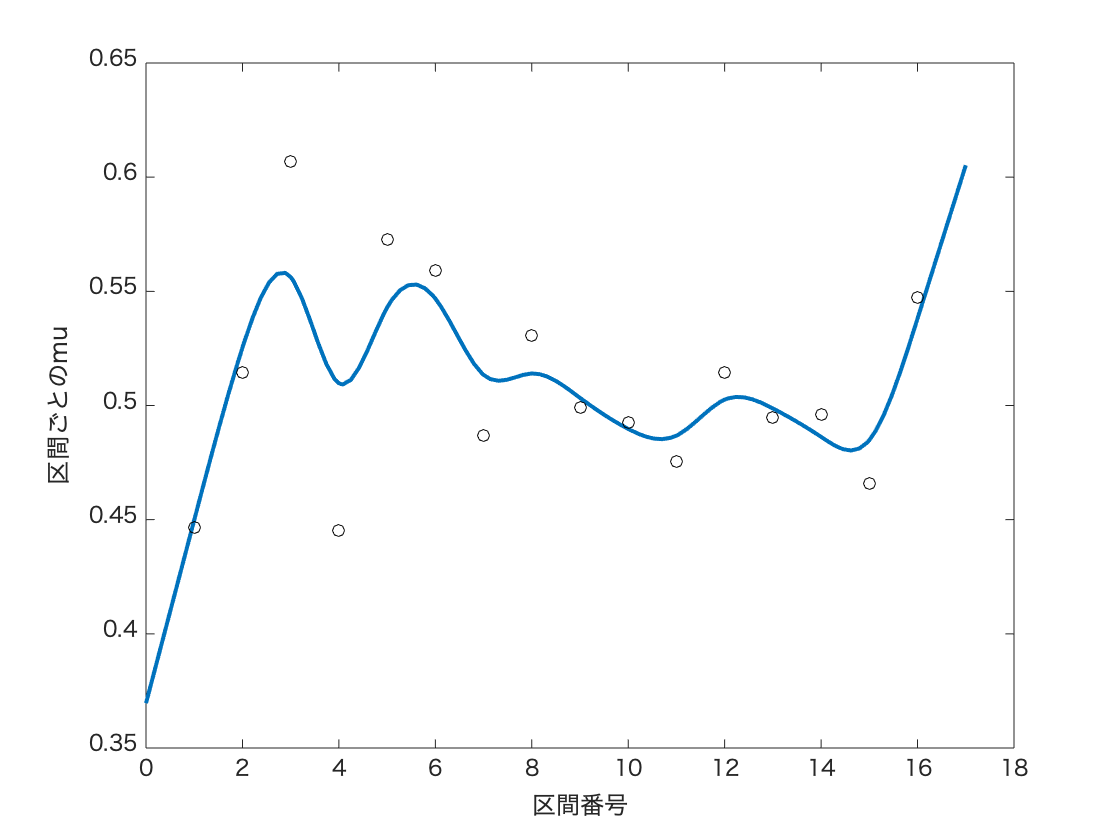

figure
fnplt(sn1);
hold on
plot(intervaldata,mulist,"ko");
xlabel("区間番号")
ylabel("区間ごとのmu")

muppvallist

muppvallist =     0.4498    0.5253    0.5562    0.5097    0.5429    0.5468    0.5134    0.5140    0.5033    0.4897    0.4868    0.5026    0.4987    0.4863    0.4848    0.5381


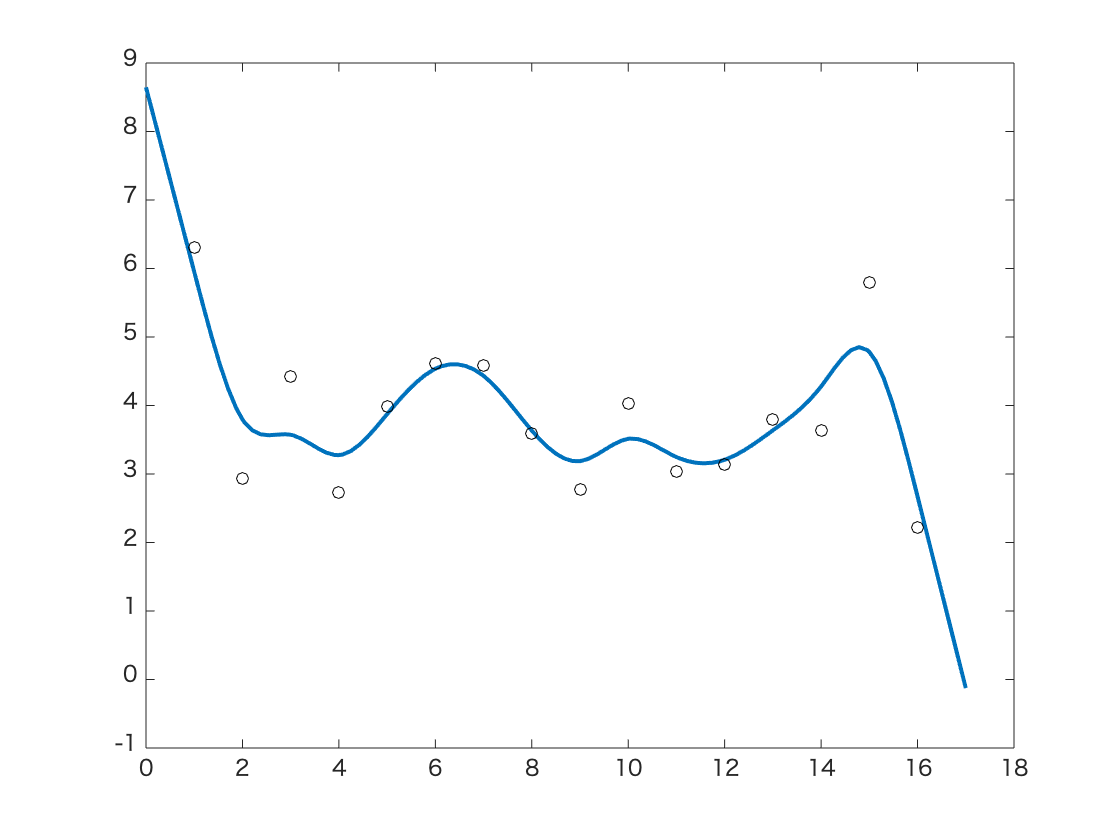

figure
fnplt(sn2);
hold on
plot(intervaldata,lambdalist,"ko");

% 3次平滑化スプラインのxqにおける値はppval(sn1,xq)で求まる
ppval(sn1,500)

ans = 33.0179

% 形状関数の観測時間ごとの値を出力
%filename = sprintf ('mlambdafunc_cum .txt');
%fileID = fopen ( filename ,'a');
%fprintf (fileID ,'%f', mlambdafunc );
%fclose ( fileID );
%filename = sprintf ('llambdafunc_cum .txt');
%fileID = fopen ( filename ,'a');
%fprintf (fileID ,'%f', llambdafunc );
%fclose ( fileID );

data1 = importdata('jumpsizedata.txt'); %区間16*サンプル15の行列
data2 = importdata('jumpsizedata2.txt'); %サンプル15*区間16の行列
t = [250 500 750 1000 1250 1500 1750 2000 2250 2500 2750 3000 3250 3500 3750 4000];
[m,n]=size(data2);
mlamfun = zeros(1,length(t));
llamfun = zeros(1,length(t));
[sn1,sn2] = splamfun(t);
for k=1:m
   mlamfun(k) = ppval(sn1,t(k));
   llamfun(k) = ppval(sn2,t(k));
end
mlamfun1(1)

ans = 0.4498

llamfun(1)

ans = 0.1345

[m,n]=size(data2)

m = 15

n = 16

lamfun1 =     0.4498    0.5253    0.5562    0.5097    0.5429    0.5468    0.5134    0.5140    0.5033    0.4897    0.4868    0.5026    0.4987    0.4863    0.4848         0


lamfun1

[y,mlf,llf]=LLIGSP_laser(1,1,5)

y = 82.1927

mlf =     0.4498    0.5253    0.5562    0.5097    0.5429    0.5468    0.5134    0.5140    0.5033    0.4897    0.4868    0.5026    0.4987    0.4863    0.4848    0.5381


llf =     5.9514    3.7965    3.5730    3.2756    3.8740    4.5360    4.4329    3.6343    3.1869    3.5140    3.2473    3.2078    3.6374    4.2780    4.7814    2.6720


syms tk k lambda
testfun(tk,lambda) = symsum(k*tk^k+lambda,k,1,8)

$$testfun(tk, lambda) = 8\,{\mathrm{tk}}^{8}+7\,{\mathrm{tk}}^{7}+6\,{\mathrm{tk}}^{6}+5\,{\mathrm{tk}}^{5}+4\,{\mathrm{tk}}^{4}+3\,{\mathrm{tk}}^{3}+2\,{\mathrm{tk}}^{2}+\mathrm{tk}+8\,\lambda$$

testfun2(tk)=(tk-1)^2

$$testfun2(tk) = {\left(\mathrm{tk}-1\right)}^{2}$$

tk = optimvar('tk');
obj = fcn2optimexpr(@testfun2,tk);

エラー: fcn2optimexpr (line 91)
関数 testfun2 が存在しません。

prob = optimproblem("Objective",obj,"ObjectiveSense","maximize");
x0.tk=0.5;
sol = solve(prob,x0);

[y,lamfun1,lamfun2]=IGM1SP_laser(1.03,0.037,412,0.003)

y = NaN

lamfun1 =     0.4498    0.5253    0.5562    0.5097    0.5429    0.5468    0.5134    0.5140    0.5033    0.4897    0.4868    0.5026    0.4987    0.4863    0.4848    0.5381


lamfun2 =     5.9514    3.7965    3.5730    3.2756    3.8740    4.5360    4.4329    3.6343    3.1869    3.5140    3.2473    3.2078    3.6374    4.2780    4.7814    2.6720


xi = optimvar('xi');
sigma = optimvar('sigma',"LowerBound",0);
alpha = optimvar("alpha","LowerBound",0);
beta = optimvar("beta","LowerBound",0);
obj = fcn2optimexpr(@IGM1SP_laser,xi,sigma,alpha,beta);
prob = optimproblem("Objective",obj,"ObjectiveSense","maximize");
x0.xi=1;
x0.sigma=1;
x0.alpha=1;
x0.beta=1;
sol = solve(prob,x0);


fmincon を使用して問題を解決しています。

局所的最小値の可能性があります。制約は満たされました。

勾配計算が未定義のため、fmincon は停止しました。制約は
制約の許容誤差値の範囲内で満たされています。

<停止条件の詳細>


val = evaluate(prob.Objective,sol)

val = -38.9278

mu = optimvar('mu');
alpha = optimvar("alpha","LowerBound",0);
beta = optimvar("beta","LowerBound",0);
obj = fcn2optimexpr(@IGM2SP_laser,mu,alpha,beta);
prob = optimproblem("Objective",obj,"ObjectiveSense","maximize");
x0.mu=1;
x0.alpha=1;
x0.beta=1;
sol = solve(prob,x0);


fmincon を使用して問題を解決しています。

局所的最小値の可能性があります。制約は満たされました。

勾配計算が未定義のため、fmincon は停止しました。制約は
制約の許容誤差値の範囲内で満たされています。

<停止条件の詳細>


evaluate(prob.Objective,sol)

ans = 82.2844

sol.mu

ans = 0.9975

sol.alpha

ans = 163.6240

sol.beta

ans = 0.0059

IGM3SP_laser(1.03,0.04,1.25)

ans = 107.3677

xi = optimvar('xi');
sigma = optimvar("sigma","LowerBound",0);
lambda = optimvar("lambda","LowerBound",0);
obj = fcn2optimexpr(@IGM3SP_laser,xi,sigma,lambda);
prob = optimproblem("Objective",obj,"ObjectiveSense","maximize");
x0.mu=1;
x0.sigma=1;
x0.lambda=1;
sol = solve(prob,x0);


fmincon を使用して問題を解決しています。

制約を満たす局所的最小値が見つかりました。

目的関数が最適性の許容誤差値の範囲内の実行可能な方向
において非減少であり、制約が制約の許容誤差値の範囲内で
満たされているため、最適化は完了しました。

<停止条件の詳細>


evaluate(prob.Objective,sol)

ans = 1.1689e+11

sol.xi

ans = 1.1320e+04

sol.sigma

ans = 7.7887e-17

sol.lambda

ans = 1.1266e+04

IGM3SPv2_laser(1.03,0.04,1.25)

エラー: sym/subsindex (line 855)
インデックス付けまたは関数定義が無効です。インデックス付けは MATLAB インデックスに従わなければなりません。関数の引数はシンボリック変数でなければならず、関数本体は sym 式でなければなりません。

エラー: IGM3SPv2_laser (line 23)
    -0.5*symsum(log(1+sigma*symsum(data(i1,j1)*lamfun2(j1)/lamfun1(j1)^2,j1,1,n)),i1,1,m)...

syms mus;
abc = [1 2 3 4;
    5 6 7 8]

abc =      1     2     3     4
     5     6     7     8


abc+0.5

ans =     1.5000    2.5000    3.5000    4.5000
    5.5000    6.5000    7.5000    8.5000


bcd = [1,2,3,4]

bcd =      1     2     3     4


sum(bcd/bcd)

ans = 1.0000

log(abc)

ans =          0    0.6931    1.0986    1.3863
    1.6094    1.7918    1.9459    2.0794


sum(log(abc))

ans =     1.6094    2.4849    3.0445    3.4657


gamma(150)

ans = 3.8089e+260

IGM2SP_laser(0.9975,112.076,0.0086)

ans = 82.2679

IGM1SP_laser(1.03402,0.0368,926.692,0.00135)

ans = 101.4153

xi = optimvar('xi');
sigma = optimvar("sigma","LowerBound",0);
alpha = optimvar("alpha","LowerBound",0);
beta = optimvar("beta","LowerBound",0);
obj = fcn2optimexpr(@IGM1SP_laser,xi,sigma,alpha,beta);
prob = optimproblem("Objective",obj,"ObjectiveSense","maximize");
x0.xi=1;
x0.sigma=1;
x0.alpha=1;
x0.beta=1;
sol = solve(prob,x0);


fmincon を使用して問題を解決しています。

局所的最小値の可能性があります。制約が満たされました。

現在のステップ サイズがステップ サイズの許容誤差値未満で、
制約が制約の許容誤差値の範囲内で満たされているため、
fmincon は停止しました。

<停止条件の詳細>


evaluate(prob.Objective,sol)

ans = 101.4153

sol.xi

ans = 1.0336

sol.sigma

ans = 0.0369

sol.alpha

ans = 426.9990

sol.beta

ans = 0.0029

IGM1SP_laser(sol.xi,sol.sigma,sol.alpha+0.1,sol.beta)

ans = Inf

mu = optimvar('mu');
alpha = optimvar("alpha","LowerBound",0);
beta = optimvar("beta","LowerBound",0);
obj = fcn2optimexpr(@IGM2SP_laser,mu,alpha,beta);
prob = optimproblem("Objective",obj,"ObjectiveSense","maximize");
x0.mu=1;
x0.alpha=1;
x0.beta=1;
sol = solve(prob,x0);


fmincon を使用して問題を解決しています。

局所的最小値の可能性があります。制約は満たされました。

勾配計算が未定義のため、fmincon は停止しました。制約は
制約の許容誤差値の範囲内で満たされています。

<停止条件の詳細>


evaluate(prob.Objective,sol)

ans = 82.2844

sol.mu

ans = 0.9975


sol.alpha

ans = 163.6240

sol.beta

ans = 0.0059

IGM2SP_laser(0.9975,163.6240,0.0059)

ans = 82.2839

xi = optimvar('xi');
sigma = optimvar("sigma","LowerBound",0);
lambda = optimvar("lambda","LowerBound",0);
obj = fcn2optimexpr(@IGM3SP_laser,xi,sigma,lambda);
prob = optimproblem("Objective",obj,"ObjectiveSense","maximize");
x0.xi=1;
x0.sigma=1;
x0.lambda=1;
sol = solve(prob,x0);


fmincon を使用して問題を解決しています。

局所的最小値の可能性があります。制約が満たされました。

現在のステップ サイズがステップ サイズの許容誤差値未満で、
制約が制約の許容誤差値の範囲内で満たされているため、
fmincon は停止しました。

<停止条件の詳細>


evaluate(prob.Objective,sol)

ans = 101.4153

sol.xi

ans = 1.0343

sol.sigma

ans = 0.0367

sol.lambda

ans = 1.2473

gammaln(690)

ans = 3.8180e+03

x = importdata("dataset/jumpcrackWu.txt");
xcum = cumsum(x,2);
z = zeros(30,1);
data = [z,xcum]

data =          0    0.6000    1.0200    1.4400    1.8900    2.4500    3.0500    3.7300
         0    0.7800    1.2000    1.8100    2.3700    3.0000    3.8400    4.7300
         0    1.2500    2.1600    3.0300    3.7400    4.8000    6.0900    7.8300
         0    1.1400    1.9400    2.7800    3.7100    4.6600    6.1000    8.0500
         0    1.1900    1.7700    2.5800    3.3200    4.4600    5.5800    7.0500
         0    1.0100    1.6500    2.4100    3.2100    3.9600    5.1400    6.5300
         0    1.2800    1.8000    2.8400    3.6100    4.8300    6.3600    8.5300
         0    0.6300    0.9800    1.5400    1.9100    2.4000    2.9900    3.6700
         0    1.4600    2.1600    3.1200    4.3400    5.5000    7.3300    9.9300
         0    0.7300    1.0300    1.4100    1.7100    2.3000    2.8800    3.5100


avedata = mean(data)

avedata =          0    0.9620    1.5300    2.2037    2.8943    3.7427    4.8067    6.2063


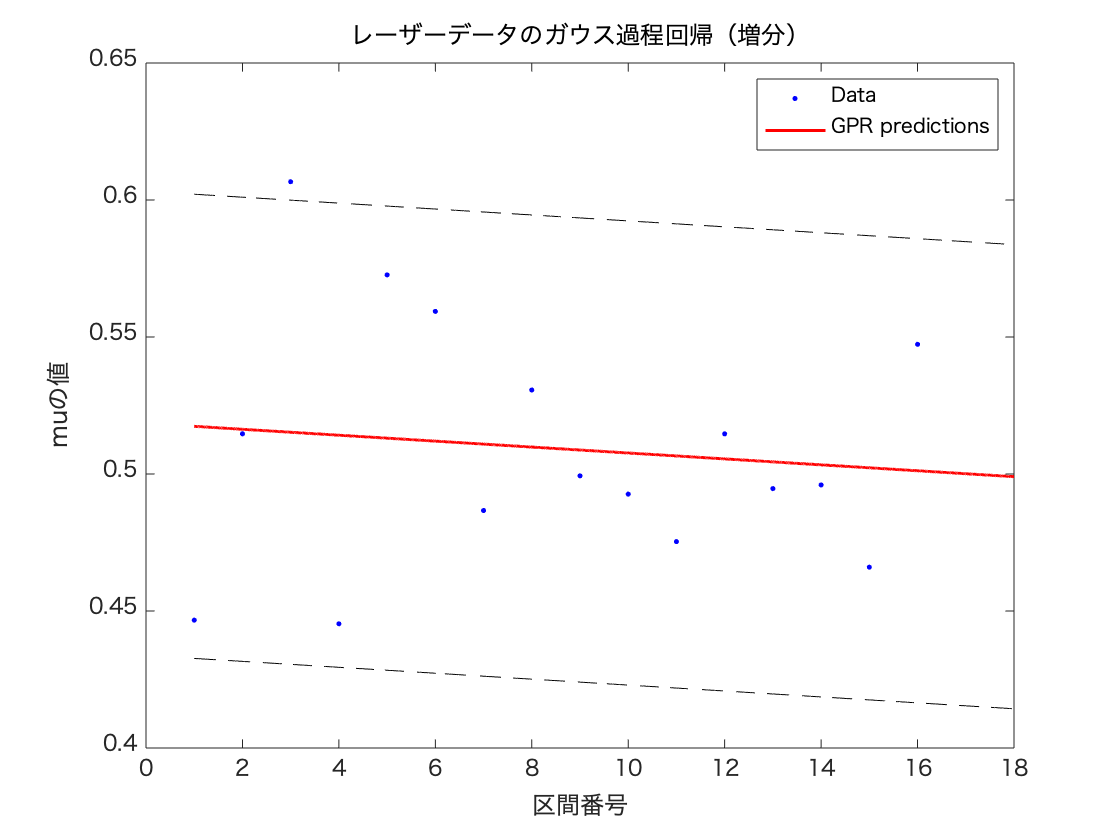


gprMdl = fitrgp(transpose(intervaldata),transpose(mulist),'Basis','linear',...
      'FitMethod','exact','PredictMethod','exact');
%gprMdl = fitrgp(transpose(tdata),transpose(mulist),'NoShellRings','KernelFunction','ardsquaredexponential',...
      %'FitMethod','sr','PredictMethod','fic','Standardize',1)
x = linspace(1,18,10000).';
[ypred,~,yci] = predict(gprMdl,x);
plot(intervaldata,mulist,'b.');
hold on;
plot(x,ypred.','r','LineWidth',1.5);
plot(x,yci(:,1),'k--');
plot(x,yci(:,2),'k--');
xlabel('区間番号');
ylabel('muの値');
title('レーザーデータのガウス過程回帰（増分）');
legend('Data','GPR predictions');
hold off

predict(gprMdl,intervaldata.')

ans =     0.5174
    0.5163
    0.5152
    0.5142
    0.5131
    0.5120
    0.5109
    0.5098
    0.5088
    0.5077


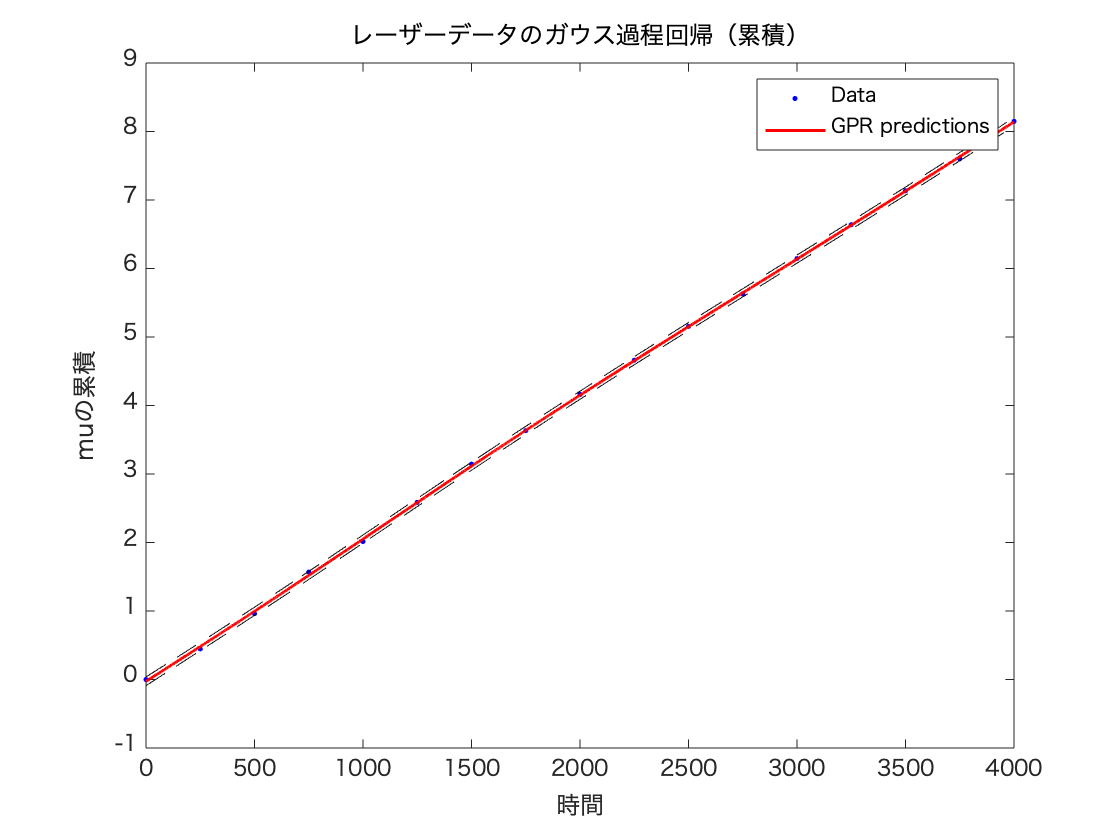

lasercumsum = cumsum([0 mulist]);
t0data = [0 tdata];
gprMdl = fitrgp(transpose(t0data),transpose(lasercumsum),'Basis','linear',...
      'FitMethod','exact','PredictMethod','exact');
x = linspace(0,4000,10000).';
[ypred,~,yci] = predict(gprMdl,x);
plot(t0data',lasercumsum.','b.');
hold on;
plot(x,ypred.','r','LineWidth',1.5);
plot(x,yci(:,1),'k--');
plot(x,yci(:,2),'k--');
xlabel('時間');
ylabel('muの累積');
title('レーザーデータのガウス過程回帰（累積）');
legend('Data','GPR predictions');
hold off

predict(gprMdl,t0data.')

ans =    -0.0258
    0.4811
    0.9962
    1.5201
    2.0509
    2.5840
    3.1141
    3.6369
    4.1501
    4.6542
